HW 2 Problem 2

Viscously Damped single DOF mass-spring system

Determine the: at 0.3s

Displacement

Velocity 

Acceleration


$${\mathrm{mx}}^{\prime \prime } +{\mathrm{cx}}^{\prime } +\mathrm{kx}=0$$



$$m\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x+c\frac{\mathrm{d}}{\mathrm{d}t}x+\mathrm{kx}=0$$



$$\frac{\mathrm{d}}{\mathrm{d}t}x=v$$



$$\frac{\mathrm{d}}{\mathrm{d}t}v=\frac{-\mathrm{cv}-\mathrm{kx}}{m}$$


clc;clear;clf;
m = 0.5;  % kg/s
k = 1000; % N/m
c = 10;   % N*s/m

x0 = 0.05; % m
v0 = 0.5;  % m/s

t0 = 0; % s
tf = 0.5; %s

dxdt=@(t,x,v) v;
dvdt=@(t,x,v) (-c*v -k*x)/m;

% % --------- Euler's Technique ----------
% N=1000;
% t=linspace(t0,tf,N+1); dt=(tf-t0)/N;
% 
% x=zeros(N+1,1); v=zeros(N+1,1);
% x(1)=x0;        v(1)=v0;
% 
% for n=1:N
%     x(n+1)=x(n)+dt*dxdt(t(n),x(n),v(n));
%     v(n+1)=v(n)+dt*dvdt(t(n),x(n),v(n));
% end
% plot(t,x,'-k'); grid on; title('Problem 21');
% hold on; plot(t,v,'-b'); hold off;


% ---------- ODE45 ----------
dzdt=@(t,z) [dxdt(t,z(1),z(2));dvdt(t,z(1),z(2))];
z0=[x0;v0];
[t,z]=ode45(dzdt,[t0,tf],z0);
plot(t,z)



% plot(t,z(:,1),'--k',t,z(:,2),'-b')
% legend('Displacement','Velocity')
% % z(:,1) is Displacement and z(:,2) is Velocity


% ---------- Cubic spline for Displacement --------------
N=30000;
tp = linspace(t0,tf,N+1);
pD=spline(t,z(:,1));
Ds=ppval(pD,tp);
hold on;plot(tp,Ds,'--b');hold off;
te=[0.3];
De=ppval(pD,te);
hold on; plot(te,De,'ok'); hold off;
fprintf('the displacement at t=%3.3fs is %f m',te,De)

the displacement at t=0.300s is 0.002726 m


% ---------- Cubic spline for Velocity --------------
tp = linspace(t0,tf,N+1);
pV=spline(t,z(:,2));
Vs=ppval(pV,tp);
hold on;plot(tp,Vs,'--');hold off;
te=[0.3];
Ve=ppval(pV,te);
hold on; plot(te,Ve,'*b'); hold off;
fprintf('the velocity at t=%3.3fs is %f m/s',te,Ve)

the velocity at t=0.300s is -0.036772 m/s


% ---------- Find Acceleration at a specific time --------------

t_before=te-1e-16;
t_after=te+1e-16;
d_time=t_after-t_before;
d_velocity=ppval(pV,t_after)-ppval(pV,t_before);
a = d_velocity/d_time;

fprintf('acceleration at t=%3.3fs is %3.5f m/s^2',te,a)

acceleration at t=0.300s is -4.71875 m/s^2

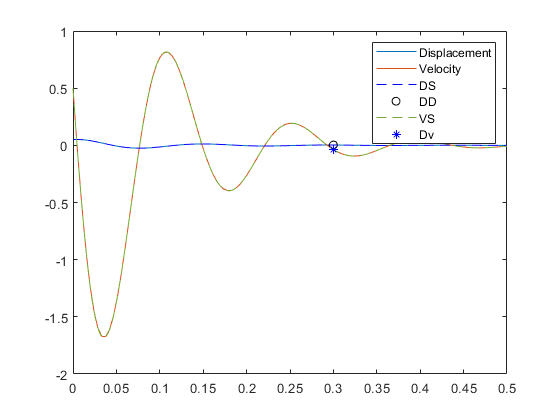


% ------------ LEGEND-------------------------------------
legend('Displacement','Velocity','DS','DD','VS','Dv','Acceleration')